# Dividing cell activity by state

% load cell IDs for cells recorded across multiple days
% load('D:\Dropbox (EinsteinMed)\Jacob\data and docs\MATLAB\live_scripts\SST_nNOS_sleep_imaging\cellIDs.mat')
cellUIDs.animal4612{1} = "4612_ 5";
cellUIDs.animal4612{2} = ["4612_ 4", "4612_ 6"];
cellUIDs.animal4627{1} = ["4627_ 2", "4627_ 1", "4627_ 3"];
cellUIDs.animal4627{2} = ["4627_ 2", "4627_ 1", "4627_ 3"];
cellUIDs.animal3300{1} = ["3300_ 1", "3300_ 2", "3300_ 3", "3300_ 4"];
cellUIDs.animal3300{2} = ["3300_ 5"];
cellUIDs.animal3300{3} = ["3300_ 6", "3300_ 7", "3300_ 8", "3300_ 9", "3300_10", "3300_11", "3300_12"];
cellUIDs.animal3300{4} = ["3300_13", "3300_ 2", "3300_14", "3300_ 1", "3300_15", "3300_16", "3300_17", "3300_18", "3300_ 3"];
cellUIDs.animal5646{1} = ["5646_ 1", "5646_ 2", "5646_ 3", "5646_ 4"];

cellUIDs.animal4094{1} = ["4094_ 1"];
cellUIDs.animal5628{1} = ["5628_ 1"];
cellUIDs.animal5628{2} = ["5628_ 2", "5628_ 3", "5628_ 4"];
cellUIDs.animal5628{3} = ["5628_ 5", "5628_ 6"];
cellUIDs.animal5628{4} = ["5628_ 7"];
% cellTypes.animal5667{1} = [1 1 1 1 1 1 1 1 1 1];

cellUIDs.animal7776{1} = ["7776_ 1", "7776_ 2", "7776_ 3"];
cellUIDs.animal7776{2} = ["7776_ 4"];
cellUIDs.animal7776{3} = ["7776_ 5", "7776_ 6", "7776_ 7"];
cellUIDs.animal7776{4} = ["7776_ 8"];

cellUIDs.animal7777{1} = ["7777_ 1"];
cellUIDs.animal7777{2} = ["7777_ 2"];

cellUIDs.animal7992{1} = ["7992_ 1", "7992_ 2", "7992_ 3", "7992_ 4"];
cellUIDs.animal7992{2} = ["7992_ 5"];
cellUIDs.animal7992{3} = ["7992_ 6", "7992_ 7", "7992_ 8"];
cellUIDs.animal7992{4} = ["7992_ 9"];

cellUIDs.animal7995{1} = ["7995_ 1"];
cellUIDs.animal7995{2} = ["7995_ 2"];

% Options for data alignment
ops.cameraTriggerChan = 11;
ops.treadmillChan = 14;
ops.overwrite = false;
ops1.method = 'baseline';

## Animal 4612

Animal 4612 Day 4 sleep

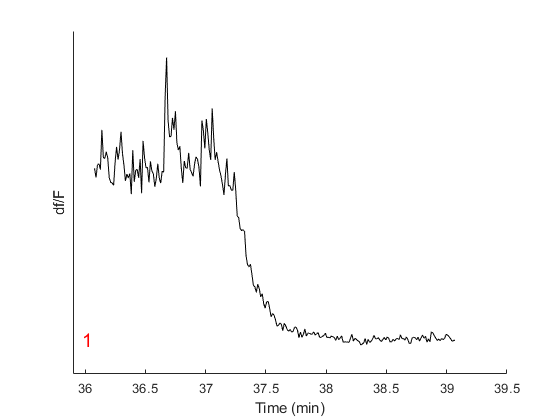

basepath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_03_09_confon_GCaMP_4612\JR_22_03_09_confon_GCaMP_4612_220309_171624';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_03_09_confon_GCaMP_4612\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;
stateInts.WAKE = SleepState.ints.WAKEstate - imgStruct.firstScopeFrameTime;

% stateInts.moveInts = FMEPupil.time(SSTnNOS.defMovementIntervals(FMEPupil.motionRaw',500,1250)); % For movement
stateInts.moveInts = imgStruct.AlignedData.faceMotion.time(SSTnNOS.defMovementIntervals(...
    imgStruct.AlignedData.faceMotion.data', 100, 1));
[~, sleepMask] = RestrictInts(stateInts.moveInts, [stateInts.REM; stateInts.NREM]);
stateInts.moveInts(sleepMask,:) = [];
stateInts.stillInts = [stateInts.moveInts(1:end-1,2) stateInts.moveInts(2:end,1)];
stateInts.stillInts = stateInts.stillInts(diff(stateInts.stillInts,1,2) > 5,:); % For stillness
stateInts.QWInts = IntersectIntervals(stateInts.WAKE, stateInts.stillInts); % For stillness w/o sleep

% Analyze session
Animal4612_sleep(1).output = analyzeSession(imgStruct, stateInts, cellUIDs.animal4612{1});

Loading cell type data extracted 28-Apr-2026 07:59:32


cellTypes = 1

Animal4612_sleep(1).output.stateActivity.NREM

ans = 1.2638

Animal4612_sleep(1).output.stateActivity.move

ans = 0.2140

Animal 4612 Day 5 sleep

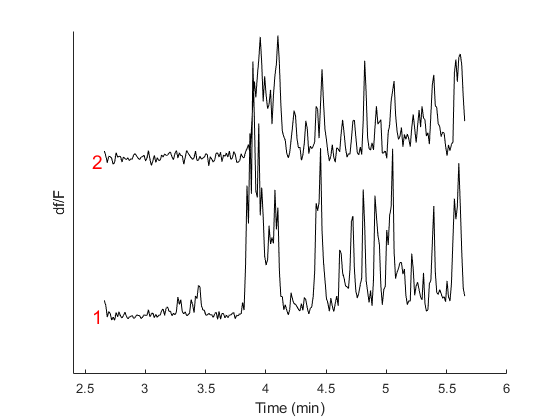

basepath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_05_11_confon_GCaMP_4612\JR_22_05_11_confon_GCaMP_4612_220511_180252';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_05_11_confon_GCaMP_4612\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;
stateInts.WAKE = SleepState.ints.WAKEstate - imgStruct.firstScopeFrameTime;

% stateInts.moveInts = FMEPupil.time(SSTnNOS.defMovementIntervals(FMEPupil.motionRaw',500,1250)); % For movement
stateInts.moveInts = imgStruct.AlignedData.faceMotion.time(SSTnNOS.defMovementIntervals(...
    imgStruct.AlignedData.faceMotion.data', 200, 2));
[~, sleepMask] = RestrictInts(stateInts.moveInts, [stateInts.REM; stateInts.NREM]);
stateInts.moveInts(sleepMask,:) = [];
stateInts.stillInts = [stateInts.moveInts(1:end-1,2) stateInts.moveInts(2:end,1)];
stateInts.stillInts = stateInts.stillInts(diff(stateInts.stillInts,1,2) > 5,:); % For stillness
stateInts.QWInts = IntersectIntervals(stateInts.WAKE, stateInts.stillInts); % For stillness w/o sleep

% Analyze session
Animal4612_sleep(2).output = analyzeSession(imgStruct, stateInts, cellUIDs.animal4612{2});

Loading cell type data extracted 28-Apr-2026 07:59:32


cellTypes =      1     2


Animal4612_sleep(2).output.stateActivity.NREM

ans = 0.0759

Animal4612_sleep(2).output.stateActivity.move

ans = 0.6540

## Animal 4627

Animal 4627 Day 5 sleep

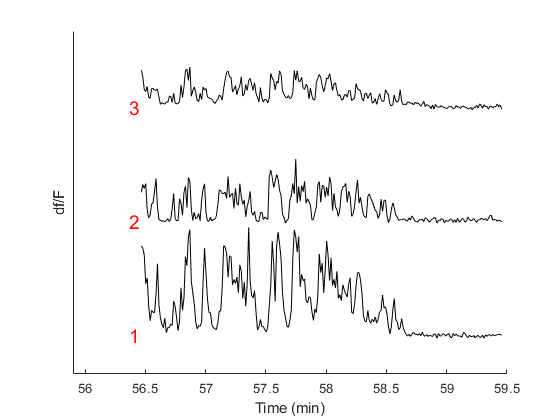

basepath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_05_09_confon_GCaMP_4627\JR_22_05_09_confon_GCaMP_4627_220509_154655';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_05_09_confon_GCaMP_4627\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;
stateInts.WAKE = SleepState.ints.WAKEstate - imgStruct.firstScopeFrameTime;

% stateInts.moveInts = FMEPupil.time(SSTnNOS.defMovementIntervals(FMEPupil.motionRaw',500,1250)); % For movement
stateInts.moveInts = imgStruct.AlignedData.faceMotion.time(SSTnNOS.defMovementIntervals(...
    imgStruct.AlignedData.faceMotion.data', 100, 1));
[~, sleepMask] = RestrictInts(stateInts.moveInts, [stateInts.REM; stateInts.NREM]);
stateInts.moveInts(sleepMask,:) = [];
stateInts.stillInts = [stateInts.moveInts(1:end-1,2) stateInts.moveInts(2:end,1)];
stateInts.stillInts = stateInts.stillInts(diff(stateInts.stillInts,1,2) > 5,:); % For stillness
stateInts.QWInts = IntersectIntervals(stateInts.WAKE, stateInts.stillInts); % For stillness w/o sleep

% Analyze session
Animal4627_sleep(1).output = analyzeSession(imgStruct, stateInts, cellUIDs.animal4627{1});

Loading cell type data extracted 28-Apr-2026 07:59:32


cellTypes =      1     1     1


Animal4627_sleep(1).output.stateActivity.NREM

ans =     1.7134
    1.0511
    0.5757


Animal4627_sleep(1).output.stateActivity.move

ans =     0.2363
    0.1703
    0.1679


Animal 4627 Day 6 sleep

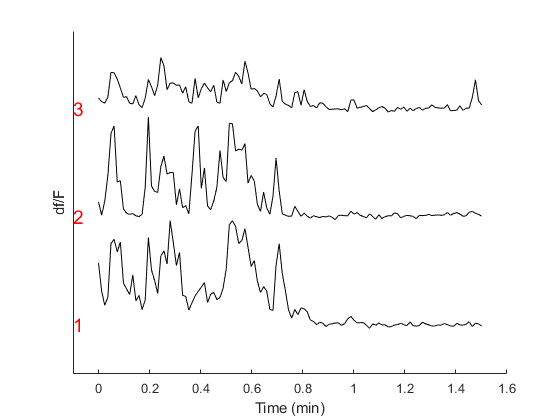

basepath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_07_12_confon_GCaMP_4627\JR_22_07_12_confon_GCaMP_4627_220712_145339';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_07_12_confon_GCaMP_4627\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;
stateInts.WAKE = SleepState.ints.WAKEstate - imgStruct.firstScopeFrameTime;

% stateInts.moveInts = FMEPupil.time(SSTnNOS.defMovementIntervals(FMEPupil.motionRaw',500,1250)); % For movement
stateInts.moveInts = imgStruct.AlignedData.faceMotion.time(SSTnNOS.defMovementIntervals(...
    imgStruct.AlignedData.faceMotion.data', 100, 1));
[~, sleepMask] = RestrictInts(stateInts.moveInts, [stateInts.REM; stateInts.NREM]);
stateInts.moveInts(sleepMask,:) = [];
stateInts.stillInts = [stateInts.moveInts(1:end-1,2) stateInts.moveInts(2:end,1)];
stateInts.stillInts = stateInts.stillInts(diff(stateInts.stillInts,1,2) > 5,:); % For stillness
stateInts.QWInts = IntersectIntervals(stateInts.WAKE, stateInts.stillInts); % For stillness w/o sleep

% Analyze session
Animal4627_sleep(2).output = analyzeSession(imgStruct, stateInts, cellUIDs.animal4627{2});

Loading cell type data extracted 28-Apr-2026 07:59:32


cellTypes =      1     1     1


Animal4627_sleep(2).output.stateActivity.NREM

ans =     0.5283
    0.3729
    0.3394


Animal4627_sleep(2).output.stateActivity.move

ans =     0.0237
    0.1278
    0.0144


## Animal 3300 (aka animal 1)

Animal 3300 Day 1 sleep

basepath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_08_03_confon_GCaMP_animal_1\JR_22_08_03_confon_GCaMP_animal_1_220803_144226';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_08_03_confon_GCaMP_animal_1\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");

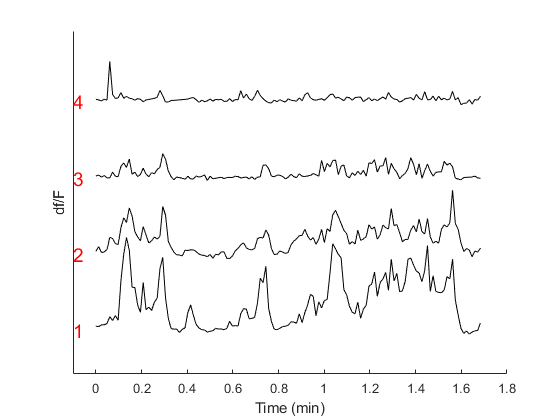

imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;
stateInts.WAKE = SleepState.ints.WAKEstate - imgStruct.firstScopeFrameTime;

% stateInts.moveInts = FMEPupil.time(SSTnNOS.defMovementIntervals(FMEPupil.motionRaw',500,1250)); % For movement
stateInts.moveInts = imgStruct.AlignedData.faceMotion.time(SSTnNOS.defMovementIntervals(...
    imgStruct.AlignedData.faceMotion.data', 100, 1));
[~, sleepMask] = RestrictInts(stateInts.moveInts, [stateInts.REM; stateInts.NREM]);
stateInts.moveInts(sleepMask,:) = [];
stateInts.stillInts = [stateInts.moveInts(1:end-1,2) stateInts.moveInts(2:end,1)];
stateInts.stillInts = stateInts.stillInts(diff(stateInts.stillInts,1,2) > 5,:); % For stillness
stateInts.QWInts = IntersectIntervals(stateInts.WAKE, stateInts.stillInts); % For stillness w/o sleep

% Analyze session
Animal3300_sleep(1).output = analyzeSession(imgStruct, stateInts, cellUIDs.animal3300{1});

Loading cell type data extracted 28-Apr-2026 07:59:32


cellTypes =      1     1     1     1


Animal3300_sleep(1).output.stateActivity.NREM

ans =     1.0606
    0.7740
    0.3482
    0.1526


Animal3300_sleep(1).output.stateActivity.move

ans =     0.0769
    0.0754
    0.0666
    0.0363


Animal 3300 Day 2 sleep

basepath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_08_05_confon_GCaMP_animal_1\JR_22_08_05_confon_GCaMP_animal_1_220805_151711';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_08_05_confon_GCaMP_animal_1\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");

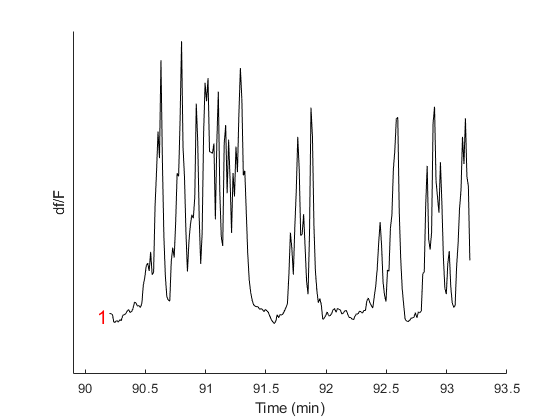

imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;
stateInts.WAKE = SleepState.ints.WAKEstate - imgStruct.firstScopeFrameTime;

% stateInts.moveInts = FMEPupil.time(SSTnNOS.defMovementIntervals(FMEPupil.motionRaw',500,1250)); % For movement
stateInts.moveInts = imgStruct.AlignedData.faceMotion.time(SSTnNOS.defMovementIntervals(...
    imgStruct.AlignedData.faceMotion.data', 100, 1));
[~, sleepMask] = RestrictInts(stateInts.moveInts, [stateInts.REM; stateInts.NREM]);
stateInts.moveInts(sleepMask,:) = [];
stateInts.stillInts = [stateInts.moveInts(1:end-1,2) stateInts.moveInts(2:end,1)];
stateInts.stillInts = stateInts.stillInts(diff(stateInts.stillInts,1,2) > 5,:); % For stillness
stateInts.QWInts = IntersectIntervals(stateInts.WAKE, stateInts.stillInts); % For stillness w/o sleep

% Analyze session
Animal3300_sleep(2).output = analyzeSession(imgStruct, stateInts, cellUIDs.animal3300{2});

Loading cell type data extracted 28-Apr-2026 07:59:32


cellTypes = 1

Animal3300_sleep(2).output.stateActivity.NREM

ans = 1.3438

Animal3300_sleep(2).output.stateActivity.move

ans = 0.1028

Animal 3300 Day 3 sleep

basepath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_08_09_confon_GCaMP_animal_1\JR_22_08_09_confon_GCaMP_animal_1_220809_140641';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_08_09_confon_GCaMP_animal_1\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");

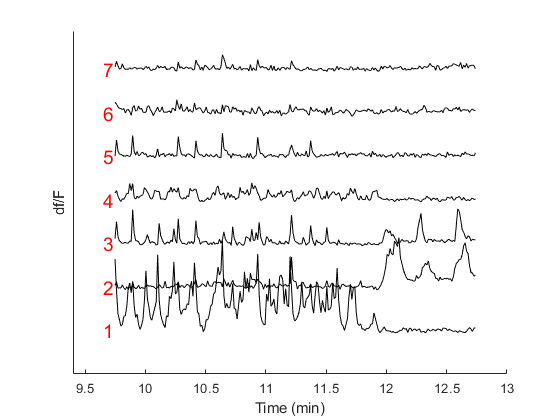

imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;
stateInts.WAKE = SleepState.ints.WAKEstate - imgStruct.firstScopeFrameTime;

% stateInts.moveInts = FMEPupil.time(SSTnNOS.defMovementIntervals(FMEPupil.motionRaw',500,1250)); % For movement
stateInts.moveInts = imgStruct.AlignedData.faceMotion.time(SSTnNOS.defMovementIntervals(...
    imgStruct.AlignedData.faceMotion.data', 100, 1));
[~, sleepMask] = RestrictInts(stateInts.moveInts, [stateInts.REM; stateInts.NREM]);
stateInts.moveInts(sleepMask,:) = [];
stateInts.stillInts = [stateInts.moveInts(1:end-1,2) stateInts.moveInts(2:end,1)];
stateInts.stillInts = stateInts.stillInts(diff(stateInts.stillInts,1,2) > 5,:); % For stillness
stateInts.QWInts = IntersectIntervals(stateInts.WAKE, stateInts.stillInts); % For stillness w/o sleep

% Analyze session
Animal3300_sleep(3).output = analyzeSession(imgStruct, stateInts, cellUIDs.animal3300{3});

Loading cell type data extracted 28-Apr-2026 07:59:32


cellTypes =      1     2     2     1     1     2     2


Animal3300_sleep(3).output.stateActivity.NREM

ans =     0.6873
    0.1695
    0.0921


Animal3300_sleep(3).output.stateActivity.move

ans =     0.0869
    0.0711
    0.0894


Animal 3300 Day 4 sleep

basepath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_08_12_confon_GCaMP_animal_1\JR_22_08_12_confon_GCaMP_animal_1_220812_160050';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_08_12_confon_GCaMP_animal_1\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");

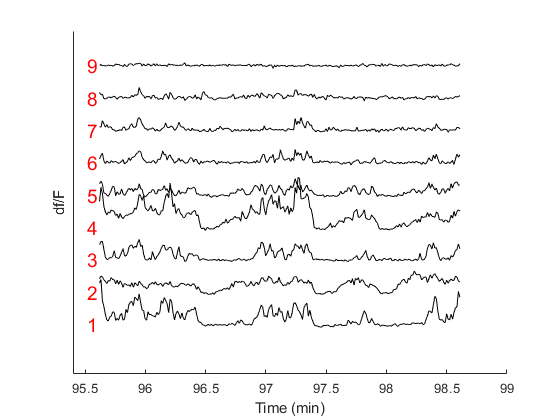

imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;
stateInts.WAKE = SleepState.ints.WAKEstate - imgStruct.firstScopeFrameTime;

% stateInts.moveInts = FMEPupil.time(SSTnNOS.defMovementIntervals(FMEPupil.motionRaw',500,1250)); % For movement
stateInts.moveInts = imgStruct.AlignedData.faceMotion.time(SSTnNOS.defMovementIntervals(...
    imgStruct.AlignedData.faceMotion.data', 100, 1));
[~, sleepMask] = RestrictInts(stateInts.moveInts, [stateInts.REM; stateInts.NREM]);
stateInts.moveInts(sleepMask,:) = [];
stateInts.stillInts = [stateInts.moveInts(1:end-1,2) stateInts.moveInts(2:end,1)];
stateInts.stillInts = stateInts.stillInts(diff(stateInts.stillInts,1,2) > 5,:); % For stillness
stateInts.QWInts = IntersectIntervals(stateInts.WAKE, stateInts.stillInts); % For stillness w/o sleep

% Analyze session
Animal3300_sleep(4).output = analyzeSession(imgStruct, stateInts, cellUIDs.animal3300{4});

Loading cell type data extracted 28-Apr-2026 07:59:32


cellTypes =      1     1     1     1     1     1     1     2     1


Animal3300_sleep(4).output.stateActivity.NREM

ans =     1.1355
    0.8523
    0.6755
    1.1554
    0.5139
    0.4694
    0.3395
    0.1282


Animal3300_sleep(4).output.stateActivity.move

ans =     0.1082
    0.0445
    0.1125
    0.0456
    0.0885
    0.1398
    0.1328
    0.0979


## Animal 5646 (aka animal 2)

Animal 5646 Day 1 sleep

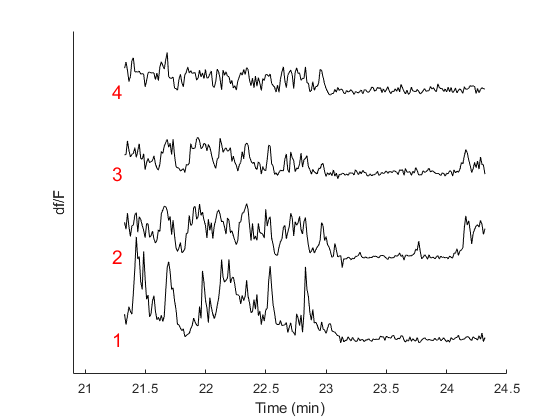

basepath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_10_13_confon_GCaMP_animal_5646\JR_22_10_13_confon_GCaMP_animal_5646_221013_152101';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_10_13_confon_GCaMP_animal_5646\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;
stateInts.WAKE = SleepState.ints.WAKEstate - imgStruct.firstScopeFrameTime;

% stateInts.moveInts = FMEPupil.time(SSTnNOS.defMovementIntervals(FMEPupil.motionRaw',500,1250)); % For movement
stateInts.moveInts = imgStruct.AlignedData.faceMotion.time(SSTnNOS.defMovementIntervals(...
    imgStruct.AlignedData.faceMotion.data', 100, 1));
[~, sleepMask] = RestrictInts(stateInts.moveInts, [stateInts.REM; stateInts.NREM]);
stateInts.moveInts(sleepMask,:) = [];
stateInts.stillInts = [stateInts.moveInts(1:end-1,2) stateInts.moveInts(2:end,1)];
stateInts.stillInts = stateInts.stillInts(diff(stateInts.stillInts,1,2) > 5,:); % For stillness
stateInts.QWInts = IntersectIntervals(stateInts.WAKE, stateInts.stillInts); % For stillness w/o sleep

% Analyze session
Animal5646_sleep(1).output = analyzeSession(imgStruct, stateInts, cellUIDs.animal5646{1});

Loading cell type data extracted 28-Apr-2026 07:59:32


cellTypes =      1     1     1     1


Animal5646_sleep(1).output.stateActivity.NREM

ans =     0.5880
    0.6462
    0.3170
    0.3621


Animal5646_sleep(1).output.stateActivity.move

ans =     0.1260
    0.0690
    0.0514
    0.0979


## Animal 4094 -- from Geoffrey

Animal 4094 Day 1 sleep

basepath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\4094\09202022_SOMnNOS\Test_Vehicle_220920_154142';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\4094\09202022_SOMnNOS\field1';

imgStruct = SSTnNOS.geoffreyDataImportWrapper(basepath);

% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;
stateInts.WAKE = SleepState.ints.WAKEstate - imgStruct.firstScopeFrameTime;

% stateInts.moveInts = FMEPupil.time(SSTnNOS.defMovementIntervals(FMEPupil.motionRaw',500,1250)); % For movement
stateInts.moveInts = imgStruct.AlignedData.faceMotion.time(SSTnNOS.defMovementIntervals(...
    imgStruct.AlignedData.faceMotion.data', 1.5, 1));
[~, sleepMask] = RestrictInts(stateInts.moveInts, [stateInts.REM; stateInts.NREM]);
stateInts.moveInts(sleepMask,:) = [];
stateInts.stillInts = [stateInts.moveInts(1:end-1,2) stateInts.moveInts(2:end,1)];
stateInts.stillInts = stateInts.stillInts(diff(stateInts.stillInts,1,2) > 5,:); % For stillness
stateInts.QWInts = IntersectIntervals(stateInts.WAKE, stateInts.stillInts); % For stillness w/o sleep

% Analyze session
Animal4094_sleep(1).output = analyzeSession(imgStruct, stateInts, cellUIDs.animal4094{1});

Loading cell type data extracted 28-Apr-2026 07:59:32


cellTypes = 1

Animal4094_sleep(1).output.stateActivity.NREM

ans = 0.3491

Animal4094_sleep(1).output.stateActivity.move

ans = 0.1460

## Animal 5628 -- from Geoffrey

Animal 5628 Day 1 sleep

basepath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\5628\11232022_SOMnNOS\5628_AFDX_221123_152657';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\5628\11232022_SOMnNOS\5628_AFDX';

imgStruct = SSTnNOS.geoffreyDataImportWrapper(basepath);

% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;
stateInts.WAKE = SleepState.ints.WAKEstate - imgStruct.firstScopeFrameTime;

% stateInts.moveInts = FMEPupil.time(SSTnNOS.defMovementIntervals(FMEPupil.motionRaw',500,1250)); % For movement
stateInts.moveInts = imgStruct.AlignedData.faceMotion.time(SSTnNOS.defMovementIntervals(...
    imgStruct.AlignedData.faceMotion.data', 1.5, 1));
[~, sleepMask] = RestrictInts(stateInts.moveInts, [stateInts.REM; stateInts.NREM]);
stateInts.moveInts(sleepMask,:) = [];
stateInts.stillInts = [stateInts.moveInts(1:end-1,2) stateInts.moveInts(2:end,1)];
stateInts.stillInts = stateInts.stillInts(diff(stateInts.stillInts,1,2) > 5,:); % For stillness
stateInts.QWInts = IntersectIntervals(stateInts.WAKE, stateInts.stillInts); % For stillness w/o sleep

% Analyze session
Animal5628_sleep(1).output = analyzeSession(imgStruct, stateInts, cellUIDs.animal5628{1});

Loading cell type data extracted 28-Apr-2026 07:59:32


cellTypes = 1

Animal5628_sleep(1).output.stateActivity.NREM

ans = 0.5377

Animal5628_sleep(1).output.stateActivity.move

ans = 0.1610

Animal 5628 Day 2 sleep

basepath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\5628\12092022_SOMnNOS\Pre_injection\AFDX1mM_221209_125812';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\5628\12092022_SOMnNOS\Pre_injection\preAFDX';

imgStruct = SSTnNOS.geoffreyDataImportWrapper(basepath);

% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;
stateInts.WAKE = SleepState.ints.WAKEstate - imgStruct.firstScopeFrameTime;

% stateInts.moveInts = FMEPupil.time(SSTnNOS.defMovementIntervals(FMEPupil.motionRaw',500,1250)); % For movement
stateInts.moveInts = imgStruct.AlignedData.faceMotion.time(SSTnNOS.defMovementIntervals(...
    imgStruct.AlignedData.faceMotion.data', 1.5, 1));
[~, sleepMask] = RestrictInts(stateInts.moveInts, [stateInts.REM; stateInts.NREM]);
stateInts.moveInts(sleepMask,:) = [];
stateInts.stillInts = [stateInts.moveInts(1:end-1,2) stateInts.moveInts(2:end,1)];
stateInts.stillInts = stateInts.stillInts(diff(stateInts.stillInts,1,2) > 5,:); % For stillness
stateInts.QWInts = IntersectIntervals(stateInts.WAKE, stateInts.stillInts); % For stillness w/o sleep

% Analyze session
Animal5628_sleep(2).output = analyzeSession(imgStruct, stateInts, cellUIDs.animal5628{2});

Loading cell type data extracted 28-Apr-2026 07:59:32


cellTypes =      1     2     2


Animal5628_sleep(2).output.stateActivity.NREM

ans = 0.6436

Animal5628_sleep(2).output.stateActivity.move

ans = 0.1243

Animal 5628 Day 3 sleep

basepath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\5628\12212022_SOMnNOS\AFDX1mM_221221_143557';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\5628\12212022_SOMnNOS\AFDX_tif';

imgStruct = SSTnNOS.geoffreyDataImportWrapper(basepath);

% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;
stateInts.WAKE = SleepState.ints.WAKEstate - imgStruct.firstScopeFrameTime;

% stateInts.moveInts = FMEPupil.time(SSTnNOS.defMovementIntervals(FMEPupil.motionRaw',500,1250)); % For movement
stateInts.moveInts = imgStruct.AlignedData.faceMotion.time(SSTnNOS.defMovementIntervals(...
    imgStruct.AlignedData.faceMotion.data', 1.5, 1));
[~, sleepMask] = RestrictInts(stateInts.moveInts, [stateInts.REM; stateInts.NREM]);
stateInts.moveInts(sleepMask,:) = [];
stateInts.stillInts = [stateInts.moveInts(1:end-1,2) stateInts.moveInts(2:end,1)];
stateInts.stillInts = stateInts.stillInts(diff(stateInts.stillInts,1,2) > 5,:); % For stillness
stateInts.QWInts = IntersectIntervals(stateInts.WAKE, stateInts.stillInts); % For stillness w/o sleep

% Analyze session
Animal5628_sleep(3).output = analyzeSession(imgStruct, stateInts, cellUIDs.animal5628{3});

Loading cell type data extracted 28-Apr-2026 07:59:32


cellTypes =      1     1


Animal5628_sleep(3).output.stateActivity.NREM

ans =     0.3484
    0.2787


Animal5628_sleep(3).output.stateActivity.move

ans =     0.0542
    0.0666


Animal 5628 Day 4 sleep

basepath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\5628\12222022_SOMnNOS\AFDX1mM_221222_150023';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\5628\12222022_SOMnNOS\AFDX_tif';

imgStruct = SSTnNOS.geoffreyDataImportWrapper(basepath);

% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;
stateInts.WAKE = SleepState.ints.WAKEstate - imgStruct.firstScopeFrameTime;

% stateInts.moveInts = FMEPupil.time(SSTnNOS.defMovementIntervals(FMEPupil.motionRaw',500,1250)); % For movement
stateInts.moveInts = imgStruct.AlignedData.faceMotion.time(SSTnNOS.defMovementIntervals(...
    imgStruct.AlignedData.faceMotion.data', 1.5, 1));
[~, sleepMask] = RestrictInts(stateInts.moveInts, [stateInts.REM; stateInts.NREM]);
stateInts.moveInts(sleepMask,:) = [];
stateInts.stillInts = [stateInts.moveInts(1:end-1,2) stateInts.moveInts(2:end,1)];
stateInts.stillInts = stateInts.stillInts(diff(stateInts.stillInts,1,2) > 5,:); % For stillness
stateInts.QWInts = IntersectIntervals(stateInts.WAKE, stateInts.stillInts); % For stillness w/o sleep

% Analyze session
Animal5628_sleep(4).output = analyzeSession(imgStruct, stateInts, cellUIDs.animal5628{4});

Loading cell type data extracted 28-Apr-2026 07:59:32


cellTypes = 1

Animal5628_sleep(4).output.stateActivity.NREM

ans = 0.4136

Animal5628_sleep(4).output.stateActivity.move

ans = 0.1373

## Animal 5667 -- from Geoffrey

Animal 5667 Day 1 sleep

No transients in cells

% basepath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\5667\12082022_SOMnNOS\AFDX1mM_221208_140135';
% basename = bz_BasenameFromBasepath(basepath);
% imgpath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\5667\12082022_SOMnNOS\AFDX';
% 
% imgStruct = SSTnNOS.geoffreyDataImportWrapper(basepath);
% 
% % Load sleep bouts and align to imaging
% load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
% stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
% stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;
% stateInts.WAKE = SleepState.ints.WAKEstate - imgStruct.firstScopeFrameTime;
% 
% % stateInts.moveInts = FMEPupil.time(SSTnNOS.defMovementIntervals(FMEPupil.motionRaw',500,1250)); % For movement
% stateInts.moveInts = imgStruct.AlignedData.faceMotion.time(SSTnNOS.defMovementIntervals(...
%     imgStruct.AlignedData.faceMotion.data', 1.5, 1));
% stateInts.stillInts = [stateInts.moveInts(1:end-1,2) stateInts.moveInts(2:end,1)];
% stateInts.stillInts = stateInts.stillInts(diff(stateInts.stillInts,1,2) > 5,:); % For stillness
% stateInts.QWInts = IntersectIntervals(stateInts.WAKE, stateInts.stillInts); % For stillness w/o sleep
% 
% % Analyze session
% Animal5667_sleep(1).output = analyzeSession(imgStruct, stateInts, cellTypes.animal5667{1});
% Animal5667_sleep(1).output.stateActivity.NREM
% Animal5667_sleep(1).output.stateActivity.move

% Options for data alignment
ops.cameraTriggerChan = 10;
ops.treadmillChan = 11;
ops.overwrite = false;
ops1.method = 'baseline';

## Animal 7776

Animal 7776 Day 1

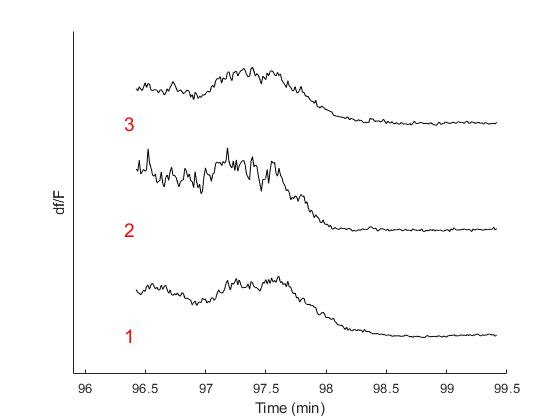

basepath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7776\7776_240416_150720';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7776\7776_240416_150720\Imaging_04_16_2024_85um';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;
stateInts.WAKE = SleepState.ints.WAKEstate - imgStruct.firstScopeFrameTime;

% stateInts.moveInts = FMEPupil.time(SSTnNOS.defMovementIntervals(FMEPupil.motionRaw',500,1250)); % For movement
stateInts.moveInts = imgStruct.AlignedData.faceMotion.time(SSTnNOS.defMovementIntervals(...
    imgStruct.AlignedData.faceMotion.data', 1000, 1));
[~, sleepMask] = RestrictInts(stateInts.moveInts, [stateInts.REM; stateInts.NREM]);
stateInts.moveInts(sleepMask,:) = [];
stateInts.stillInts = [stateInts.moveInts(1:end-1,2) stateInts.moveInts(2:end,1)];
stateInts.stillInts = stateInts.stillInts(diff(stateInts.stillInts,1,2) > 5,:); % For stillness
stateInts.QWInts = IntersectIntervals(stateInts.WAKE, stateInts.stillInts); % For stillness w/o sleep

% Analyze session
Animal7776(1).output = analyzeSession(imgStruct, stateInts, cellUIDs.animal7776{1});

Loading cell type data extracted 28-Apr-2026 07:59:32


cellTypes =      1     1     1


Animal7776(1).output.stateActivity.NREM

ans =     0.8664
    1.4927
    1.0301


Animal7776(1).output.stateActivity.move

ans =     0.3174
    0.1564
    0.2791


Animal 7776 Day 2

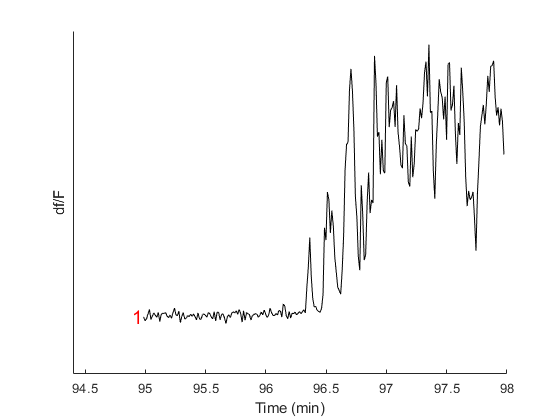

basepath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7776\7776_240417_114748';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7776\7776_240417_114748\Imaging_04_17_2024_200um';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...




% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;
stateInts.WAKE = SleepState.ints.WAKEstate - imgStruct.firstScopeFrameTime;

% stateInts.moveInts = FMEPupil.time(SSTnNOS.defMovementIntervals(FMEPupil.motionRaw',500,1250)); % For movement
stateInts.moveInts = imgStruct.AlignedData.faceMotion.time(SSTnNOS.defMovementIntervals(...
    imgStruct.AlignedData.faceMotion.data', 1000, 1));
[~, sleepMask] = RestrictInts(stateInts.moveInts, [stateInts.REM; stateInts.NREM]);
stateInts.moveInts(sleepMask,:) = [];
stateInts.stillInts = [stateInts.moveInts(1:end-1,2) stateInts.moveInts(2:end,1)];
stateInts.stillInts = stateInts.stillInts(diff(stateInts.stillInts,1,2) > 5,:); % For stillness
stateInts.QWInts = IntersectIntervals(stateInts.WAKE, stateInts.stillInts); % For stillness w/o sleep

% Analyze session
Animal7776(2).output = analyzeSession(imgStruct, stateInts, cellUIDs.animal7776{2});

Loading cell type data extracted 28-Apr-2026 07:59:32


cellTypes = 1

Animal7776(2).output.stateActivity.NREM

ans = 1.5498

Animal7776(2).output.stateActivity.move

ans = 0.0939

Animal 7776 Day 3

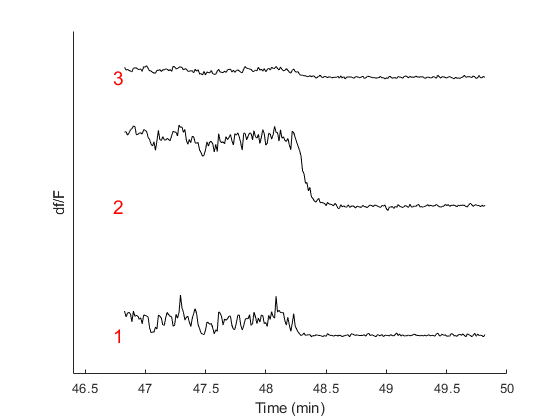

basepath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7776\7776_240418_115444';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7776\7776_240418_115444\Imaging_04_18_2024_15um';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;
stateInts.WAKE = SleepState.ints.WAKEstate - imgStruct.firstScopeFrameTime;

% stateInts.moveInts = FMEPupil.time(SSTnNOS.defMovementIntervals(FMEPupil.motionRaw',500,1250)); % For movement
stateInts.moveInts = imgStruct.AlignedData.faceMotion.time(SSTnNOS.defMovementIntervals(...
    imgStruct.AlignedData.faceMotion.data', 1500, 1));
[~, sleepMask] = RestrictInts(stateInts.moveInts, [stateInts.REM; stateInts.NREM]);
stateInts.moveInts(sleepMask,:) = [];
stateInts.stillInts = [stateInts.moveInts(1:end-1,2) stateInts.moveInts(2:end,1)];
stateInts.stillInts = stateInts.stillInts(diff(stateInts.stillInts,1,2) > 5,:); % For stillness
stateInts.QWInts = IntersectIntervals(stateInts.WAKE, stateInts.stillInts); % For stillness w/o sleep

% Analyze session
Animal7776(3).output = analyzeSession(imgStruct, stateInts, cellUIDs.animal7776{3});

Loading cell type data extracted 28-Apr-2026 07:59:32


cellTypes =      1     1     1


Animal7776(3).output.stateActivity.NREM

ans =     0.5235
    1.7080
    0.2505


Animal7776(3).output.stateActivity.move

ans =     0.0479
    0.1843
    0.0396


Animal 7776 Day 4

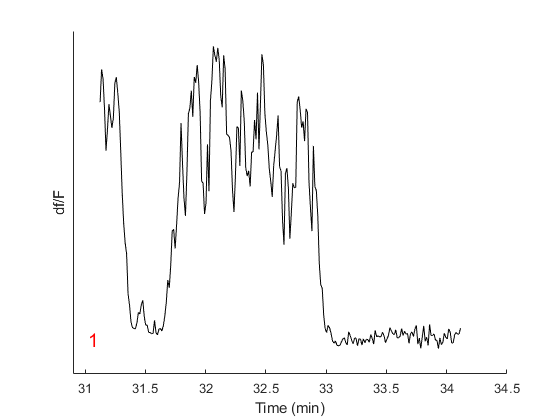

basepath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7776\7776_240419_155705';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7776\7776_240419_155705\Imaging_04_19_2024_70um';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;
stateInts.WAKE = SleepState.ints.WAKEstate - imgStruct.firstScopeFrameTime;

% stateInts.moveInts = FMEPupil.time(SSTnNOS.defMovementIntervals(FMEPupil.motionRaw',500,1250)); % For movement
stateInts.moveInts = imgStruct.AlignedData.faceMotion.time(SSTnNOS.defMovementIntervals(...
    imgStruct.AlignedData.faceMotion.data', 1500, 1));
[~, sleepMask] = RestrictInts(stateInts.moveInts, [stateInts.REM; stateInts.NREM]);
stateInts.moveInts(sleepMask,:) = [];
stateInts.stillInts = [stateInts.moveInts(1:end-1,2) stateInts.moveInts(2:end,1)];
stateInts.stillInts = stateInts.stillInts(diff(stateInts.stillInts,1,2) > 5,:); % For stillness
stateInts.QWInts = IntersectIntervals(stateInts.WAKE, stateInts.stillInts); % For stillness w/o sleep

% Analyze session
Animal7776(4).output = analyzeSession(imgStruct, stateInts, cellUIDs.animal7776{4});

Loading cell type data extracted 28-Apr-2026 07:59:32


cellTypes = 1

Animal7776(4).output.stateActivity.NREM

ans = 1.4384

Animal7776(4).output.stateActivity.move

ans = 0.2042

## Animal 7777

Animal 7777 Day 1

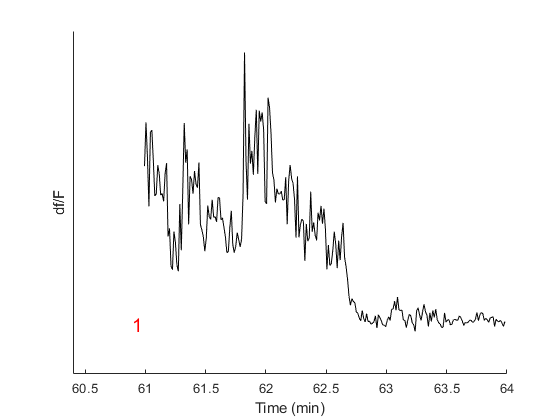

basepath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7777\7777_240501_160828';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7777\7777_240501_160828\05-01-2024-30um';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;
stateInts.WAKE = SleepState.ints.WAKEstate - imgStruct.firstScopeFrameTime;

% stateInts.moveInts = FMEPupil.time(SSTnNOS.defMovementIntervals(FMEPupil.motionRaw',500,1250)); % For movement
stateInts.moveInts = imgStruct.AlignedData.faceMotion.time(SSTnNOS.defMovementIntervals(...
    imgStruct.AlignedData.faceMotion.data', 1500, 1));
[~, sleepMask] = RestrictInts(stateInts.moveInts, [stateInts.REM; stateInts.NREM]);
stateInts.moveInts(sleepMask,:) = [];
stateInts.stillInts = [stateInts.moveInts(1:end-1,2) stateInts.moveInts(2:end,1)];
stateInts.stillInts = stateInts.stillInts(diff(stateInts.stillInts,1,2) > 5,:); % For stillness
stateInts.QWInts = IntersectIntervals(stateInts.WAKE, stateInts.stillInts); % For stillness w/o sleep

% Analyze session
Animal7777(1).output = analyzeSession(imgStruct, stateInts, cellUIDs.animal7777{1});

Loading cell type data extracted 28-Apr-2026 07:59:32


cellTypes = 1

Animal7777(1).output.stateActivity.NREM

ans = 0.6793

Animal7777(1).output.stateActivity.move

ans = 0.1071

Animal 7777 Day 2

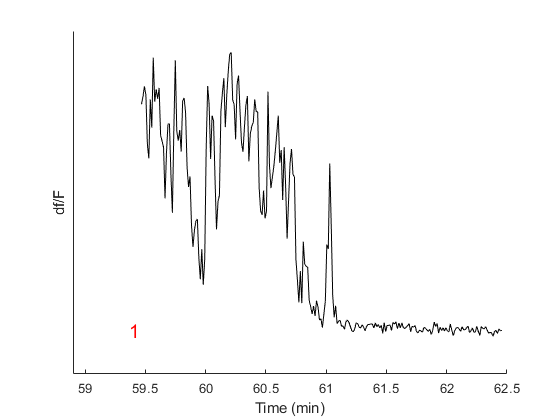

basepath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7777\7777_240508_144803';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7777\7777_240508_144803\Imaging_05-08-2024-80um';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;
stateInts.WAKE = SleepState.ints.WAKEstate - imgStruct.firstScopeFrameTime;

% stateInts.moveInts = FMEPupil.time(SSTnNOS.defMovementIntervals(FMEPupil.motionRaw',500,1250)); % For movement
stateInts.moveInts = imgStruct.AlignedData.faceMotion.time(SSTnNOS.defMovementIntervals(...
    imgStruct.AlignedData.faceMotion.data', 1500, 1));
[~, sleepMask] = RestrictInts(stateInts.moveInts, [stateInts.REM; stateInts.NREM]);
stateInts.moveInts(sleepMask,:) = [];
stateInts.stillInts = [stateInts.moveInts(1:end-1,2) stateInts.moveInts(2:end,1)];
stateInts.stillInts = stateInts.stillInts(diff(stateInts.stillInts,1,2) > 5,:); % For stillness
stateInts.QWInts = IntersectIntervals(stateInts.WAKE, stateInts.stillInts); % For stillness w/o sleep

% Analyze session
Animal7777(2).output = analyzeSession(imgStruct, stateInts, cellUIDs.animal7777{2});

Loading cell type data extracted 28-Apr-2026 07:59:32


cellTypes = 1

Animal7777(2).output.stateActivity.NREM

ans = 1.4103

Animal7777(2).output.stateActivity.move

ans = 0.0904

## Animal 7992

Animal 7992 Day 1

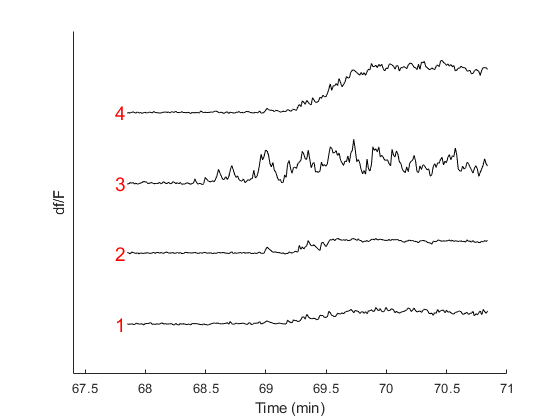

basepath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7992\7992_240416_120003';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7992\7992_240416_120003\Imaging_04_16_2024_70um_000';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;
stateInts.WAKE = SleepState.ints.WAKEstate - imgStruct.firstScopeFrameTime;

% stateInts.moveInts = FMEPupil.time(SSTnNOS.defMovementIntervals(FMEPupil.motionRaw',500,1250)); % For movement
stateInts.moveInts = imgStruct.AlignedData.faceMotion.time(SSTnNOS.defMovementIntervals(...
    imgStruct.AlignedData.faceMotion.data', 1500, 1));
[~, sleepMask] = RestrictInts(stateInts.moveInts, [stateInts.REM; stateInts.NREM]);
stateInts.moveInts(sleepMask,:) = [];
stateInts.stillInts = [stateInts.moveInts(1:end-1,2) stateInts.moveInts(2:end,1)];
stateInts.stillInts = stateInts.stillInts(diff(stateInts.stillInts,1,2) > 5,:); % For stillness
stateInts.QWInts = IntersectIntervals(stateInts.WAKE, stateInts.stillInts); % For stillness w/o sleep

% Analyze session
Animal7992(1).output = analyzeSession(imgStruct, stateInts, cellUIDs.animal7992{1});

Loading cell type data extracted 28-Apr-2026 07:59:32


cellTypes =      1     1     1     1


Animal7992(1).output.stateActivity.NREM

ans =     0.7800
    0.8929
    1.5653
    1.7092


Animal7992(1).output.stateActivity.move

ans =     0.1739
    0.2557
    0.4145
    0.5236


Animal 7992 Day 2

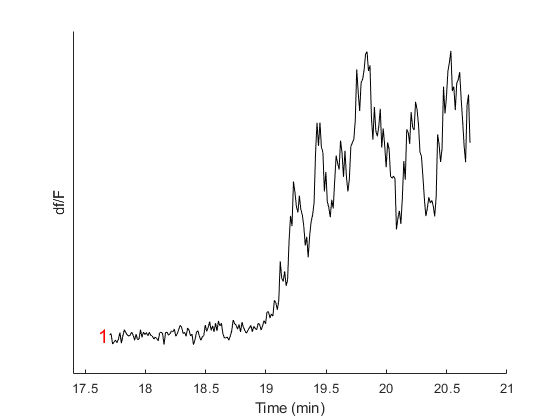

basepath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7992\7992_240418_143030';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7992\7992_240418_143030\Imaging_04_18_2024_10um';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;
stateInts.WAKE = SleepState.ints.WAKEstate - imgStruct.firstScopeFrameTime;

% stateInts.moveInts = FMEPupil.time(SSTnNOS.defMovementIntervals(FMEPupil.motionRaw',500,1250)); % For movement
stateInts.moveInts = imgStruct.AlignedData.faceMotion.time(SSTnNOS.defMovementIntervals(...
    imgStruct.AlignedData.faceMotion.data', 1500, 1));
[~, sleepMask] = RestrictInts(stateInts.moveInts, [stateInts.REM; stateInts.NREM]);
stateInts.moveInts(sleepMask,:) = [];
stateInts.stillInts = [stateInts.moveInts(1:end-1,2) stateInts.moveInts(2:end,1)];
stateInts.stillInts = stateInts.stillInts(diff(stateInts.stillInts,1,2) > 5,:); % For stillness
stateInts.QWInts = IntersectIntervals(stateInts.WAKE, stateInts.stillInts); % For stillness w/o sleep

% Analyze session
Animal7992(2).output = analyzeSession(imgStruct, stateInts, cellUIDs.animal7992{2});

Loading cell type data extracted 28-Apr-2026 07:59:32


cellTypes = 1

Animal7992(2).output.stateActivity.NREM

ans = 1.0546

Animal7992(2).output.stateActivity.move

ans = 0.1586

Animal 7992 Day 3

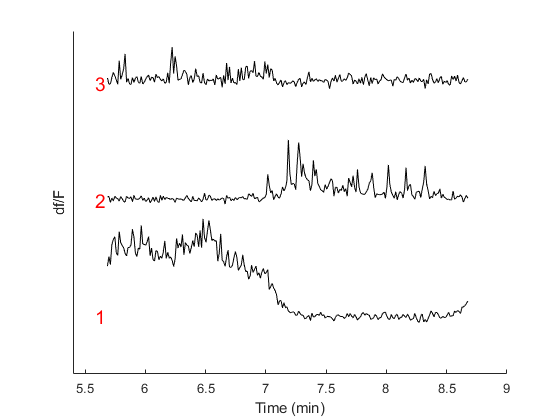

basepath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7992\7992_240419_132238';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7992\7992_240419_132238\Imaging_04_19_2024_155um';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;
stateInts.WAKE = SleepState.ints.WAKEstate - imgStruct.firstScopeFrameTime;

% stateInts.moveInts = FMEPupil.time(SSTnNOS.defMovementIntervals(FMEPupil.motionRaw',500,1250)); % For movement
stateInts.moveInts = imgStruct.AlignedData.faceMotion.time(SSTnNOS.defMovementIntervals(...
    imgStruct.AlignedData.faceMotion.data', 1500, 1));
[~, sleepMask] = RestrictInts(stateInts.moveInts, [stateInts.REM; stateInts.NREM]);
stateInts.moveInts(sleepMask,:) = [];
stateInts.stillInts = [stateInts.moveInts(1:end-1,2) stateInts.moveInts(2:end,1)];
stateInts.stillInts = stateInts.stillInts(diff(stateInts.stillInts,1,2) > 5,:); % For stillness
stateInts.QWInts = IntersectIntervals(stateInts.WAKE, stateInts.stillInts); % For stillness w/o sleep

% Analyze session
Animal7992(3).output = analyzeSession(imgStruct, stateInts, cellUIDs.animal7992{3});

Loading cell type data extracted 28-Apr-2026 07:59:32


cellTypes =      1     2     1


Animal7992(3).output.stateActivity.NREM

ans =     1.1656
    0.2209


Animal7992(3).output.stateActivity.move

ans =     0.1930
    0.2044


Animal 7992 Day 4

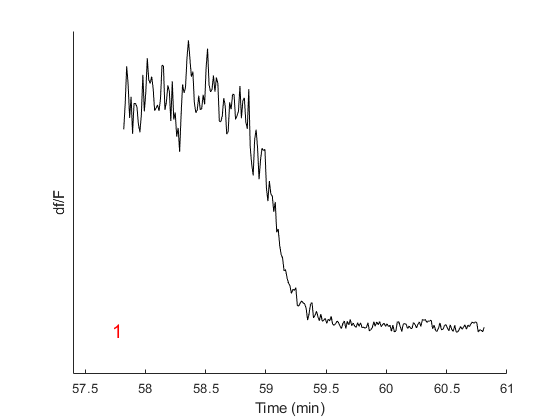

basepath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7992\7992_240422_124051';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7992\7992_240422_124051\Imaging_04_22_2024_140um';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;
stateInts.WAKE = SleepState.ints.WAKEstate - imgStruct.firstScopeFrameTime;

% stateInts.moveInts = FMEPupil.time(SSTnNOS.defMovementIntervals(FMEPupil.motionRaw',500,1250)); % For movement
stateInts.moveInts = imgStruct.AlignedData.faceMotion.time(SSTnNOS.defMovementIntervals(...
    imgStruct.AlignedData.faceMotion.data', 1500, 1));
[~, sleepMask] = RestrictInts(stateInts.moveInts, [stateInts.REM; stateInts.NREM]);
stateInts.moveInts(sleepMask,:) = [];
stateInts.stillInts = [stateInts.moveInts(1:end-1,2) stateInts.moveInts(2:end,1)];
stateInts.stillInts = stateInts.stillInts(diff(stateInts.stillInts,1,2) > 5,:); % For stillness
stateInts.QWInts = IntersectIntervals(stateInts.WAKE, stateInts.stillInts); % For stillness w/o sleep

% Analyze session
Animal7992(4).output = analyzeSession(imgStruct, stateInts, cellUIDs.animal7992{4});

Loading cell type data extracted 28-Apr-2026 07:59:32


cellTypes = 1

Animal7992(4).output.stateActivity.NREM

ans = 2.1046

Animal7992(4).output.stateActivity.move

ans = 0.2647

## Animal 7995

Animal 7995 Day 1

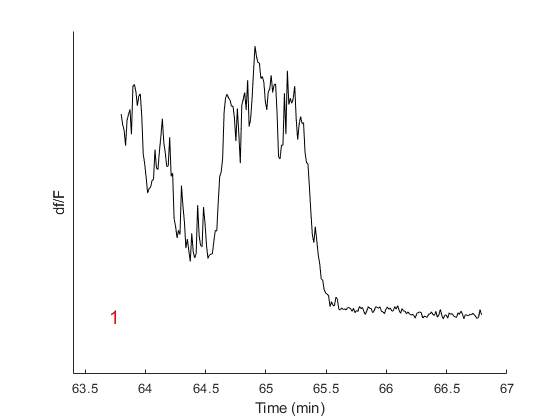

basepath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7995\7995_240501_125221';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7995\7995_240501_125221\Imaging_05-01-2024-0um';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...




% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;
stateInts.WAKE = SleepState.ints.WAKEstate - imgStruct.firstScopeFrameTime;

% stateInts.moveInts = FMEPupil.time(SSTnNOS.defMovementIntervals(FMEPupil.motionRaw',500,1250)); % For movement
stateInts.moveInts = imgStruct.AlignedData.faceMotion.time(SSTnNOS.defMovementIntervals(...
    imgStruct.AlignedData.faceMotion.data', 1500, 1));
[~, sleepMask] = RestrictInts(stateInts.moveInts, [stateInts.REM; stateInts.NREM]);
stateInts.moveInts(sleepMask,:) = [];
stateInts.stillInts = [stateInts.moveInts(1:end-1,2) stateInts.moveInts(2:end,1)];
stateInts.stillInts = stateInts.stillInts(diff(stateInts.stillInts,1,2) > 5,:); % For stillness
stateInts.QWInts = IntersectIntervals(stateInts.WAKE, stateInts.stillInts); % For stillness w/o sleep

% Analyze session
Animal7995(1).output = analyzeSession(imgStruct, stateInts, cellUIDs.animal7995{1});

Loading cell type data extracted 28-Apr-2026 07:59:32


cellTypes = 1

Animal7995(1).output.stateActivity.NREM

ans = 1.0184

Animal7995(1).output.stateActivity.move

ans = 0.1555

Animal 7995 Day 2

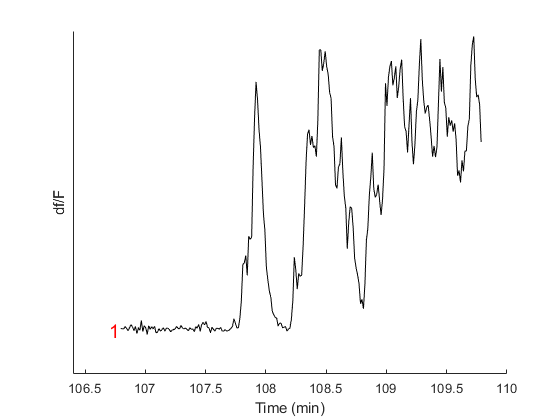

basepath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7995\7995_240514_144726';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7995\7995_240514_144726\Imaging_05-14-2024-170um';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;
stateInts.WAKE = SleepState.ints.WAKEstate - imgStruct.firstScopeFrameTime;

% stateInts.moveInts = FMEPupil.time(SSTnNOS.defMovementIntervals(FMEPupil.motionRaw',500,1250)); % For movement
stateInts.moveInts = imgStruct.AlignedData.faceMotion.time(SSTnNOS.defMovementIntervals(...
    imgStruct.AlignedData.faceMotion.data', 1500, 1));
[~, sleepMask] = RestrictInts(stateInts.moveInts, [stateInts.REM; stateInts.NREM]);
stateInts.moveInts(sleepMask,:) = [];
stateInts.stillInts = [stateInts.moveInts(1:end-1,2) stateInts.moveInts(2:end,1)];
stateInts.stillInts = stateInts.stillInts(diff(stateInts.stillInts,1,2) > 5,:); % For stillness
stateInts.QWInts = IntersectIntervals(stateInts.WAKE, stateInts.stillInts); % For stillness w/o sleep

% Analyze session
Animal7995(2).output = analyzeSession(imgStruct, stateInts, cellUIDs.animal7995{2});

Loading cell type data extracted 28-Apr-2026 07:59:32


cellTypes = 1

Animal7995(2).output.stateActivity.NREM

ans = 2.3017

Animal7995(2).output.stateActivity.move

ans = 0.0922

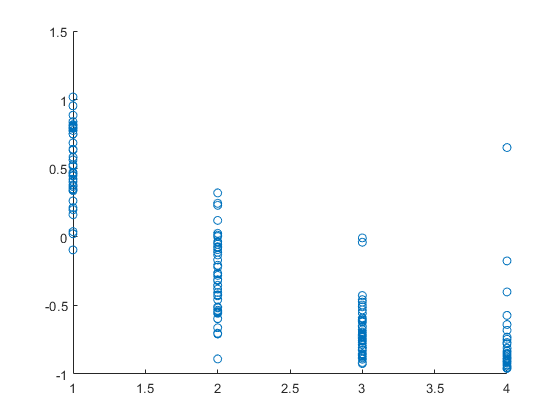

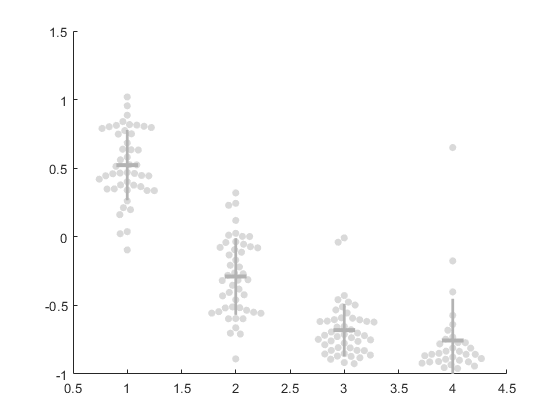

combinedOutput = combineAcrossAnimals([Animal4612_sleep, Animal4627_sleep, Animal3300_sleep, Animal5646_sleep, Animal4094_sleep, Animal5628_sleep,...
    Animal7776 Animal7777 Animal7992 Animal7995]);

[~, uniqueCellInd] = unique(combinedOutput.cellUIDs);

uniqueCellInd(15) = [];
figure
beeInds = ones(size(combinedOutput.stateActivityZ(uniqueCellInd, :))) + (0:3);
beeInds = beeInds(:);
beeData = combinedOutput.stateActivityZ(uniqueCellInd,:);
beeswarm(beeInds, beeData(:),...
    'colormap', [.7 .7 .7; .7 .7 .7; .7 .7 .7; .7 .7 .7], 'sort_style', 'down', 'overlay','sd');

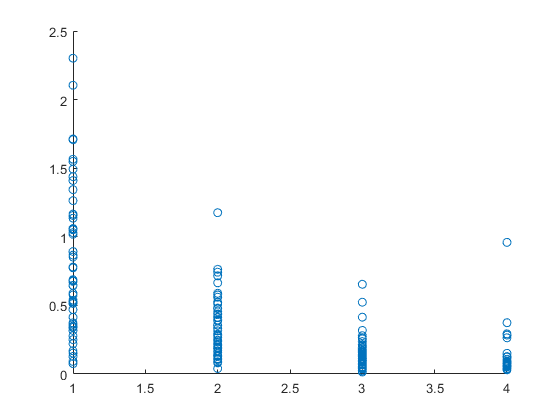

figure
beeInds = ones(size(combinedOutput.stateActivity)) + (0:3);
beeInds = beeInds(:);
beeswarm(beeInds, combinedOutput.stateActivity(:),...
    'colormap', [.6 .6 .6; .6 .6 .6; .6 .6 .6; .6 .6 .6], 'sort_style', 'down', 'overlay','sd');

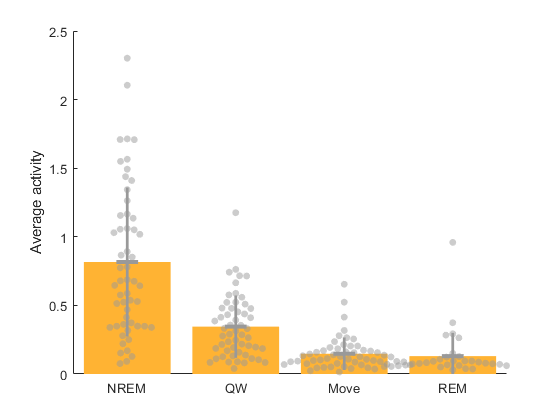

hold on
bar(mean(combinedOutput.stateActivity,'omitnan'),'FaceColor',[1 .7 .2], 'EdgeColor','none')
chi=get(gca, 'Children');
%Reverse the stacking order so that the patch overlays the line
set(gca, 'Children',flipud(chi))
ylabel('Average activity')
xticks(1:4)
xticklabels(combinedOutput.stateLabels)

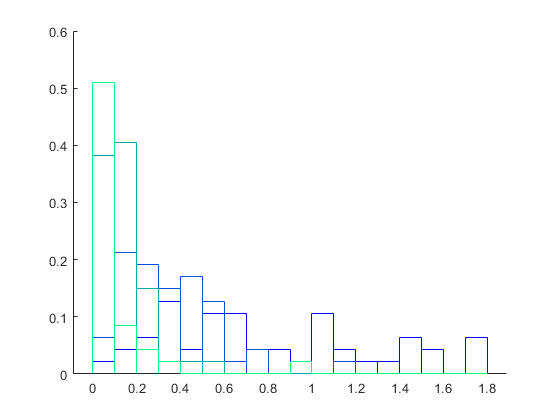

figure; hold on
edges = 0:.1:1.8;
cmap = winter(4);
for i = 1:4
    histogram(combinedOutput.stateActivity(uniqueCellInd,i),edges,'FaceColor','none','EdgeColor',cmap(i,:),...
        'Normalization','probability')
end

figure; hold on
edges = 0:.05:2;
binCenter = edges(1:end-1) + .05

binCenter =     0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000    1.0500    1.1000    1.1500    1.2000    1.2500    1.3000    1.3500    1.4000    1.4500    1.5000    1.5500    1.6000    1.6500    1.7000    1.7500    1.8000    1.8500    1.9000    1.9500    2.0000


cmap = winter(4);
for i = 1:4
    subplot(4,1,i)
    activityslice = combinedOutput.stateActivity(uniqueCellInd,i);
    count = histcounts(activityslice(~isnan(activityslice)),edges,'Normalization','probability');
    plot(binCenter, smoothdata(count, 'gaussian',10), 'Color', cmap(i,:),'LineWidth',2)
    sum(smoothdata(count, 'gaussian',10))
    box off
    set(gca, 'xcolor', 'none')
%     ylim([0 .3])
end

ans = 0.9652

ans = 1.0245

ans = 1.0222

ans = 0.9858

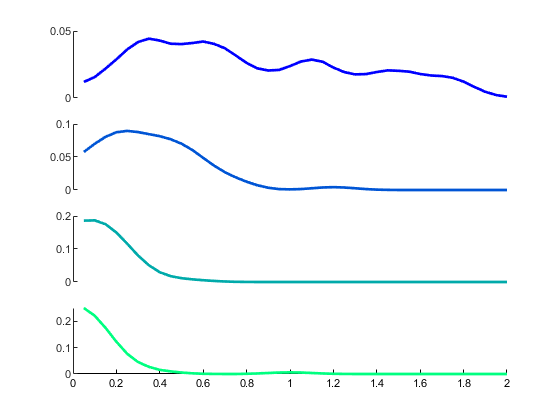

set(gca, 'xcolor', 'k')

% legend(combinedOutput.stateLabels)
figure
violin(combinedOutput.stateActivity(uniqueCellInd,:),'medc', [], 'edgecolor', [], 'facecolor', 'b')

ans =   1×4 Patch array:

    Patch    Patch    Patch    Patch


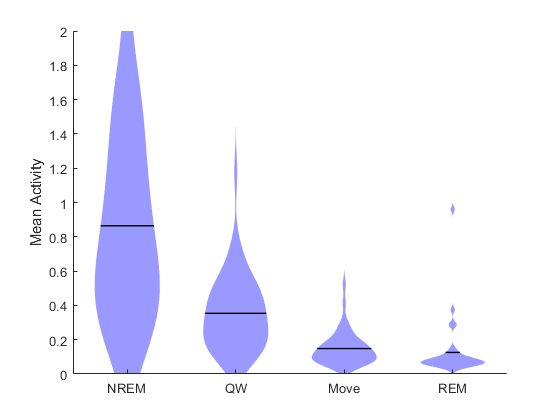

ylim([0 2])
box off
legend off
xticks(1:4)
xticklabels(combinedOutput.stateLabels)
set(gca, 'TickLength', [0.01 0.025])
ylabel('Mean Activity')

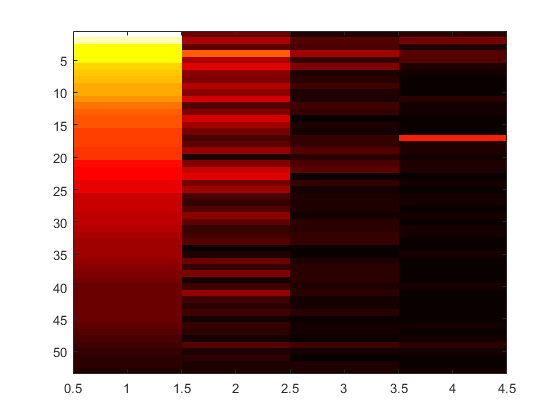

[~, sortedInds] = sort(combinedOutput.stateActivity(:,1),'descend');
figure
imagesc(combinedOutput.stateActivity(sortedInds(1:end-1),:))
colormap hot

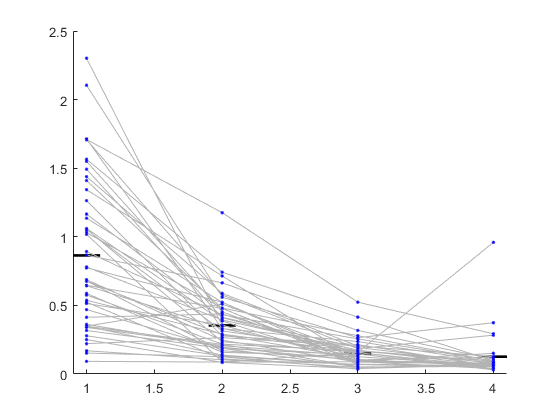

figure; hold on
plot([.9 1.1], repelem(nanmean(combinedOutput.stateActivity(uniqueCellInd,1)),2),...
    'k', 'linewidth',2)
plot([.9 1.1]+ 1, repelem(nanmean(combinedOutput.stateActivity(uniqueCellInd,2)),2),...
    'k', 'linewidth',2)
plot([.9 1.1]+ 2, repelem(nanmean(combinedOutput.stateActivity(uniqueCellInd,3)),2),...
    'k', 'linewidth',2)
plot([.9 1.1]+ 3, repelem(nanmean(combinedOutput.stateActivity(uniqueCellInd,4)),2),...
    'k', 'linewidth',2)
plot(combinedOutput.stateActivity(uniqueCellInd,:)','.-','Color',[.7 .7 .7],'MarkerEdgeColor','b','MarkerFaceColor','b')
xlim([.9 4.1])
box off

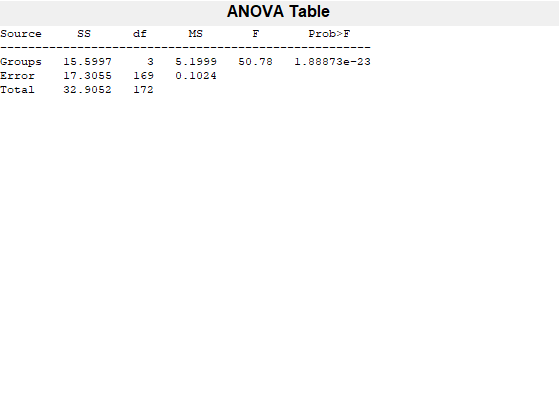

p = 1.8887e-23

tbl = 4×6 cell array
    {'Source'}    {'SS'     }    {'df' }    {'MS'      }    {'F'       }    {'Prob>F'    }
    {'Groups'}    {[15.5997]}    {[  3]}    {[  5.1999]}    {[ 50.7807]}    {[1.8887e-23]}
    {'Error' }    {[17.3055]}    {[169]}    {[  0.1024]}    {0×0 double}    {0×0 double  }
    {'Total' }    {[32.9052]}    {[172]}    {0×0 double}    {0×0 double}    {0×0 double  }


stats = struct with fields:
    gnames: {4×1 cell}
         n: [47 47 47 32]
    source: 'anova1'
     means: [0.8641 0.3539 0.1482 0.1260]
        df: 169
         s: 0.3200


[p,tbl,stats] = anova1(combinedOutput.stateActivity(uniqueCellInd,:))

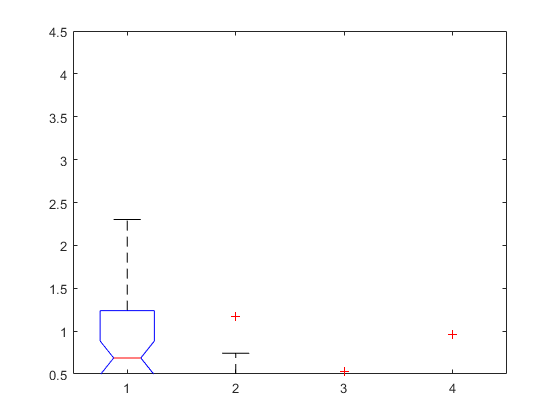

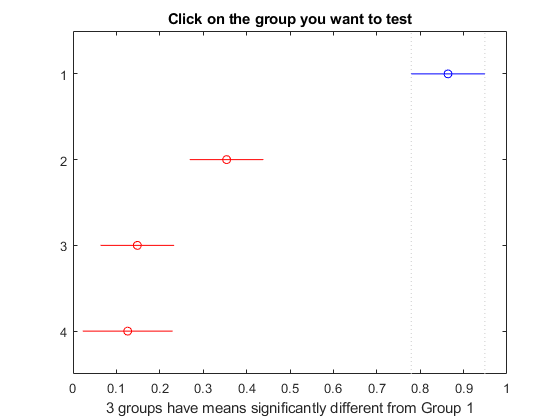

ans =     1.0000    2.0000    0.3406    0.5102    0.6797    0.0000
    1.0000    3.0000    0.5463    0.7159    0.8855    0.0000
    1.0000    4.0000    0.5497    0.7381    0.9265    0.0000
    2.0000    3.0000    0.0361    0.2057    0.3753    0.0099
    2.0000    4.0000    0.0395    0.2280    0.4164    0.0102
    3.0000    4.0000   -0.1662    0.0222    0.2106    0.9903


multcompare(stats)


figure
beeInds = ones(size(combinedOutput.cellCellCorr(uniqueCellInd,:))) + (0:3);
beeInds = beeInds(:);
tmp = combinedOutput.cellCellCorr(uniqueCellInd,:)

tmp =     0.4878    0.5853    0.2534       NaN
    0.2937    0.2662    0.1594       NaN
    0.1537    0.2013   -0.0094       NaN
    0.1675    0.1320    0.0317       NaN
    0.5867    0.4922    0.2845    0.0074
    0.1661    0.2811    0.2474    0.0193
    0.1380    0.1239    0.1559    0.0848
    0.3855    0.4285    0.1984       NaN
    0.6123    0.6687    0.2284       NaN
    0.5659    0.5751    0.1983       NaN


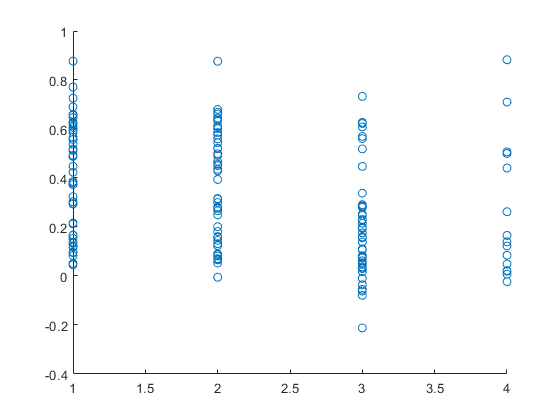

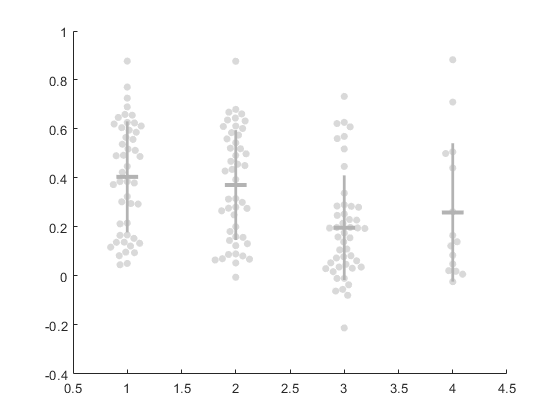

beeswarm(beeInds, tmp(:),...
    'colormap', [.7 .7 .7; .7 .7 .7; .7 .7 .7; .7 .7 .7], 'sort_style', 'down', 'overlay','sd');

## Animal X

Animal X Day XX sleep

% basepath = '';
% basename = bz_BasenameFromBasepath(basepath);
% imgpath = '';
%
% s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
% imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);
% imgStruct = alignImagingData(imgStruct,basepath,10,ops);
%
% % Load sleep bouts and align to imaging
% load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
% stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
% stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;
% stateInts.WAKE = SleepState.ints.WAKEstate - imgStruct.firstScopeFrameTime;
%
% % stateInts.moveInts = FMEPupil.time(SSTnNOS.defMovementIntervals(FMEPupil.motionRaw',500,1250)); % For movement
% stateInts.moveInts = imgStruct.AlignedData.faceMotion.time(SSTnNOS.defMovementIntervals(...
%     imgStruct.AlignedData.faceMotion.data', 100, 1));
% stateInts.stillInts = [stateInts.moveInts(1:end-1,2) stateInts.moveInts(2:end,1)];
% stateInts.stillInts = stateInts.stillInts(diff(stateInts.stillInts,1,2) > 5,:); % For stillness
% stateInts.QWInts = IntersectIntervals(stateInts.WAKE, stateInts.stillInts); % For stillness w/o sleep
%
% % Analyze session
% AnimalX_sleep(XX).output = analyzeSession(imgStruct, stateInts, cellTypes.animalX{XX});

function combinedAnimal = combineAcrossAnimals(animals)

stateActivity = [];
stateActivityZ = [];
cellCellCorr = [];
cellUIDs = [];
for i = 1:length(animals)
    stateActivity = [stateActivity; ...
        horzcat(animals(i).output.stateActivity.NREM, animals(i).output.stateActivity.QW, animals(i).output.stateActivity.move,...
        animals(i).output.stateActivity.REM)];
    stateActivityZ = [stateActivityZ; ...
        horzcat(animals(i).output.stateActivityZ.NREM, animals(i).output.stateActivityZ.QW, animals(i).output.stateActivityZ.move,...
        animals(i).output.stateActivityZ.REM)];
    cellCellCorr = [cellCellCorr; ...
        horzcat(animals(i).output.cellCellCorr.NREM', animals(i).output.cellCellCorr.QW', animals(i).output.cellCellCorr.move', ...
        animals(i).output.cellCellCorr.REM')];
    cellUIDs = [cellUIDs, animals(i).output.cellUIDs];
end

stateLabels = {'NREM', 'QW', 'Move', 'REM'};

combinedAnimal.stateActivity = stateActivity;
combinedAnimal.stateActivityZ = stateActivityZ;
combinedAnimal.cellCellCorr = cellCellCorr;
combinedAnimal.stateLabels = stateLabels;
combinedAnimal.cellUIDs = cellUIDs;

end

function output = analyzeSession(imgStruct, stateInts, cellUIDs)

% Analyze session
[~, stateMask.NREM] = RestrictInts(imgStruct.deltaF.time', stateInts.NREM);
[~, stateMask.REM] = RestrictInts(imgStruct.deltaF.time', stateInts.REM);
[~, stateMask.move] = RestrictInts(imgStruct.deltaF.time', stateInts.moveInts);
[~, stateMask.QW] = RestrictInts(imgStruct.deltaF.time', stateInts.QWInts);

cellTypes = SSTnNOS.getCellType(cellUIDs)

cellmask = cellTypes == 1;

stateActivity.NREM = mean(imgStruct.deltaF.data(cellmask,stateMask.NREM),2);
stateActivity.REM = mean(imgStruct.deltaF.data(cellmask,stateMask.REM),2);
stateActivity.move = mean(imgStruct.deltaF.data(cellmask,stateMask.move),2);
stateActivity.QW = mean(imgStruct.deltaF.data(cellmask,stateMask.QW),2);

Zdata = (imgStruct.deltaF.data ./ mean(imgStruct.deltaF.data,2)) - 1;

stateActivityZ.NREM = mean(Zdata(cellmask,stateMask.NREM),2);
stateActivityZ.REM = mean(Zdata(cellmask,stateMask.REM),2);
stateActivityZ.move = mean(Zdata(cellmask,stateMask.move),2);
stateActivityZ.QW = mean(Zdata(cellmask,stateMask.QW),2);

if sum(cellmask) > 0
    cellCellCorr.NREM = getOffDiags(corr(imgStruct.deltaF.data(cellmask,stateMask.NREM)'));
    if sum(stateMask.REM) ~= 0
        cellCellCorr.REM = getOffDiags(corr(imgStruct.deltaF.data(cellmask,stateMask.REM)'));
    else
        cellCellCorr.REM = nan(1, (sum(cellmask).^2 - sum(cellmask)) / 2); % if no REM impute nans for each pair
    end
    cellCellCorr.move = getOffDiags(corr(imgStruct.deltaF.data(cellmask,stateMask.move)'));
    cellCellCorr.QW = getOffDiags(corr(imgStruct.deltaF.data(cellmask,stateMask.QW)'));
else
    cellCellCorr.NREM = [];
    cellCellCorr.REM = [];
    cellCellCorr.move = [];
    cellCellCorr.QW = [];
end

output.stateActivity = stateActivity;
output.stateActivityZ = stateActivityZ;
output.cellCellCorr = cellCellCorr;
output.cellUIDs = cellUIDs(cellmask);

end

function uniqueOffDiags = getOffDiags(symmetricalMatrix)

uniqueOffDiags = [];
for i = 1:size(symmetricalMatrix,1)
    for j = 1:size(symmetricalMatrix,1)
        if i > j
            uniqueOffDiags = [uniqueOffDiags symmetricalMatrix(i,j)];
        end
    end
end

end
